# CAPÍTULO 08 - ESTADO TENSIONAL, DEFORMACIONES Y TEORÍAS DE RESISTENCIA

Introduce un tensor simétrico de tensiones o deformaciones para obtener valores principales, tensión sobre una cara y criterios de resistencia.

Dimensión: el tensor ya es 3D. Las curvas de Mohr son representaciones 2D de ese estado; la vista de direcciones principales permite comprobar su orientación espacial.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

tipo="tensiones" interpreta matriz en Pa; tipo="deformaciones" la interpreta en m/m. Cada fila y columna sigue x,y,z. normalCara puede tener cualquier longitud distinta de cero. El incremento térmico se suma a la deformación normal, no al cortante.

tipo="tensiones";
matriz=[80 25 0; 25 -20 10; 0 10 5]*1e6;
E=210e9; nu=.3; alpha=12e-6; deltaT=0;
normalCara=[1 1 0];
limiteElastico=250e6;

## 2. Ley de Hooke y valores principales


$$\boldsymbol\varepsilon=\frac{1+\nu}{E}\boldsymbol\sigma-\frac{\nu}{E}\operatorname{tr}(\boldsymbol\sigma)\mathbf{I}+\alpha\Delta T\mathbf{I}$$



$$\boldsymbol\sigma\mathbf{v}_i=\sigma_i\mathbf{v}_i,\qquad \sigma_1\geq\sigma_2\geq\sigma_3$$


if tipo=="tensiones"
    S=matriz;
else
    assert(tipo=="deformaciones" && E>0 && nu>-1 && nu<.5,'Datos invalidos.');
    ee=matriz-alpha*deltaT*eye(3);
    G=E/(2*(1+nu)); lambda=E*nu/((1+nu)*(1-2*nu));
    S=2*G*ee+lambda*trace(ee)*eye(3);
end
resultado=rm_tensor(S,E,nu);
deformaciones=resultado.epsilon+alpha*deltaT*eye(3);
assert(norm(normalCara)>0,'La normal no puede ser nula.');
n=normalCara(:)/norm(normalCara);
traccion=S*n; sigmaNormal=n'*traccion;
tauCara=norm(traccion-sigmaNormal*n);
disp(table(resultado.principales/1e6,'VariableNames',{'Tensiones_principales_MPa'}));

    Tensiones_principales_MPa
    _________________________

              85.968         
              7.7474         
             -28.715         



disp('Deformaciones tensoriales:'); disp(deformaciones);

Deformaciones tensoriales:
   1.0e-03 *

    0.4024    0.1548         0
    0.1548   -0.2167    0.0619
         0    0.0619   -0.0619



disp(table(sigmaNormal/1e6,tauCara/1e6,resultado.VM/1e6,resultado.Tresca/1e6, ...
    'VariableNames',{'Normal_MPa','Cortante_cara_MPa','Von_Mises_MPa','Tresca_MPa'}));

    Normal_MPa    Cortante_cara_MPa    Von_Mises_MPa    Tresca_MPa
    __________    _________________    _____________    __________

        55             50.498             101.49          114.68  



## 3. Cortante máximo y criterios


$$\mathbf{t}=\boldsymbol\sigma\mathbf{n},\qquad \sigma_n=\mathbf{n}^T\boldsymbol\sigma\mathbf{n},\qquad \tau_n=\|\mathbf{t}-\sigma_n\mathbf{n}\|$$



$$\tau_{\max}=\frac{\sigma_1-\sigma_3}{2},\quad \sigma_{\mathrm{VM}}=\sqrt{\frac{(\sigma_1-\sigma_2)^2+(\sigma_2-\sigma_3)^2+(\sigma_3-\sigma_1)^2}{2}}$$


assert(limiteElastico>0,'Limite resistente positivo.');
nVM=limiteElastico/max(resultado.VM,realmin);
nTresca=limiteElastico/max(resultado.Tresca,realmin);
disp(table(nVM,nTresca));

     nVM      nTresca
    ______    _______

    2.4633    2.1799 



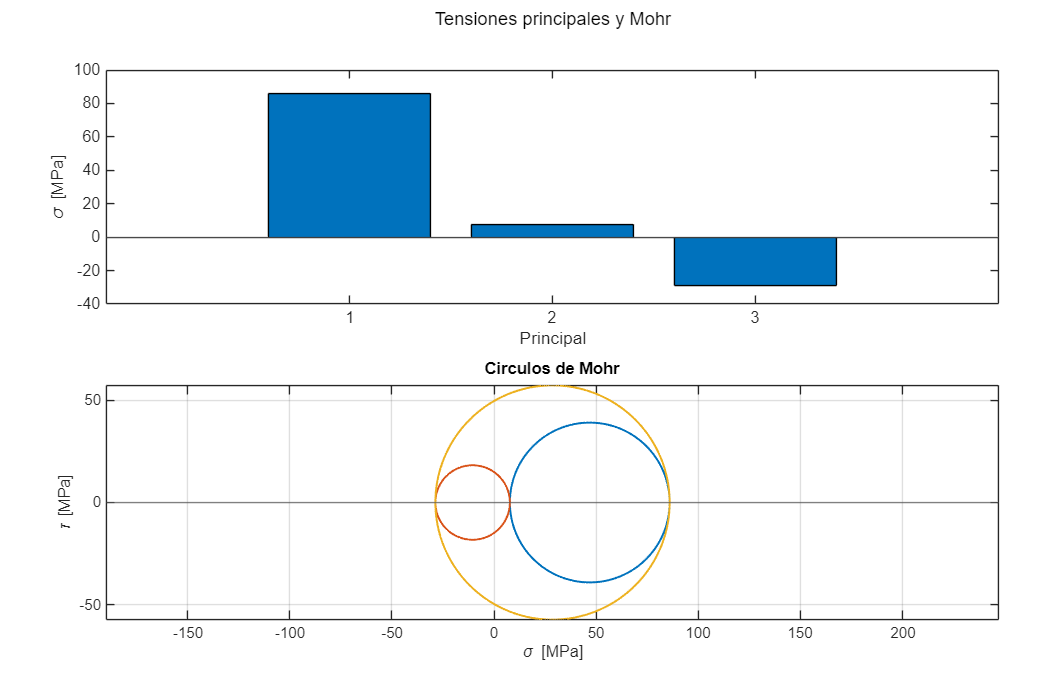

[figura,ejes]=rm_figura(2,'Tensiones principales y Mohr');
bar(ejes(1),resultado.principales/1e6); yline(ejes(1),0,'Color',[.35 .35 .35]);
ylabel(ejes(1),'\sigma [MPa]'); xlabel(ejes(1),'Principal');
rm_mohr(ejes(2),resultado);

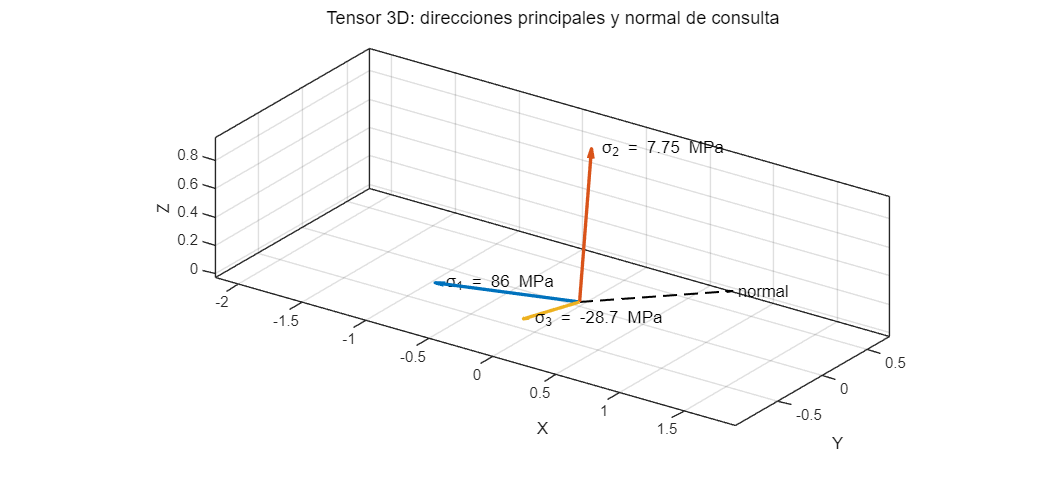

[figura,ejes]=rm_figura(1,'Tensor 3D: direcciones principales y normal de consulta');hold(ejes(1),'on');
colores=lines(3);
for j=1:3
    v=resultado.direcciones(:,j);
    quiver3(ejes(1),0,0,0,v(1),v(2),v(3),0,'Color',colores(j,:),'LineWidth',2);
    text(ejes(1),v(1),v(2),v(3),sprintf(' σ_%d = %.3g MPa',j,resultado.principales(j)/1e6));
end
quiver3(ejes(1),0,0,0,n(1),n(2),n(3),0,'k--','LineWidth',1.2);
text(ejes(1),n(1),n(2),n(3),' normal');
axis(ejes(1),'equal');grid(ejes(1),'on');view(ejes(1),35,24);
xlabel(ejes(1),'X');ylabel(ejes(1),'Y');zlabel(ejes(1),'Z');

## Funciones utilizadas

rm_tensor: analiza un tensor simétrico. Aquí ordena las tensiones principales y aplica Hooke.

trace: suma la diagonal de una matriz. Aquí obtiene la parte volumétrica de tensión o deformación.

eye: crea una matriz identidad. Aquí representa la contribución hidrostática y térmica.

norm: calcula una magnitud vectorial. Aquí normaliza la cara y obtiene su cortante.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Estado homogéneo en un punto de un material elástico lineal isótropo. Las deformaciones fuera de la diagonal son tensoriales: epsilon_xy=gamma_xy/2. No calcula un campo espacial a partir de cargas de contorno.

Conexión con lo anterior: Generaliza la ley de Hooke del capítulo 1 y suministra los criterios usados en el capítulo 9.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 08: calculo completado.');

Capitulo 08: calculo completado.
